clear

close all
clf

load cuvicSVM.mat
modelo = cubicSVM;

% Create a cascade detector object.
Detector = vision.CascadeObjectDetector('FrontalFaceLBP');
 
% Read a video frame and run the face detector.
videoReader = VideoReader('Pablo.mp4');
 
set(gca,'nextplot','replacechildren'); 
video = VideoWriter('video3.avi');

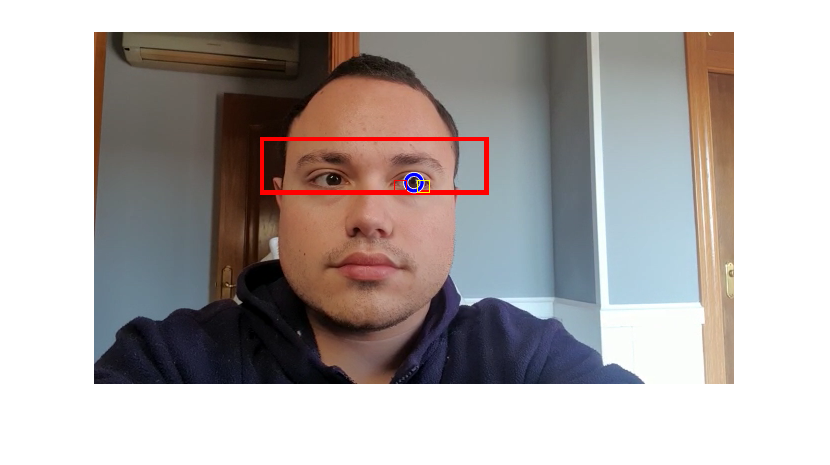

open(video);
i = 0;
while hasFrame(videoReader)
    % get the next frame
    videoFrame = readFrame(videoReader);
    bbox = step(Detector, videoFrame);
    
    % Draw the returned bounding box around the detected face.
    
    %videoFrame = insertShape(videoFrame, 'Rectangle', bbox);
    
    imagen = videoFrame;
    if mod(i, 5) == 0
        [soloOjos, ~, caraMarcada, inicioHorizontal, inicioVertical, factorInverso, ~, ~, ~, encontrado1] = caras(imagen, modelo);
        if encontrado1 == true
    %     imshow(soloOjos);
    %     imshow(masOjos);
    %     imshow(caraMarcada);
    %     hold on;
    %     plot(finalHorizontal + inicioHorizontal, finalVertical + inicioVertical, 'o');
    %     hold off;
            [imin, imax, center, radii, ~, ~, medio, encontrado] = lagrimal(soloOjos);
            inicioHorizontal2 = round(width(soloOjos)/2) * factorInverso;
            inicioVertical2 = 0;
            if encontrado == true
                imshow(caraMarcada);
                center(1) = (center(1) * factorInverso) + inicioHorizontal + inicioHorizontal2;
                center(2) = (center(2) * factorInverso) + inicioVertical + inicioVertical2;
                hold on;
                radii(1) = radii(1) * 0.5;
                viscircles(center, radii,'Color','b');
                plot(inicioHorizontal + inicioHorizontal2 + (imin * factorInverso), (medio * factorInverso) + inicioVertical + inicioVertical2 , 's','MarkerSize', 10 ,'Color','r');
                plot(inicioHorizontal + inicioHorizontal2 + (imax * factorInverso), (medio * factorInverso) + inicioVertical + inicioVertical2, 's','MarkerSize', 10 ,'Color','yellow');
                hold off;
            end
        end
        pause(0.9);
        
        frame = getframe(gcf);
        writeVideo(video, frame); 
    end
    i = i + 1;
end

close(video);

imagen = imread("DataFaces/images/0418383c3c3c3c1c.jpg");
%imagen = videoFrame;

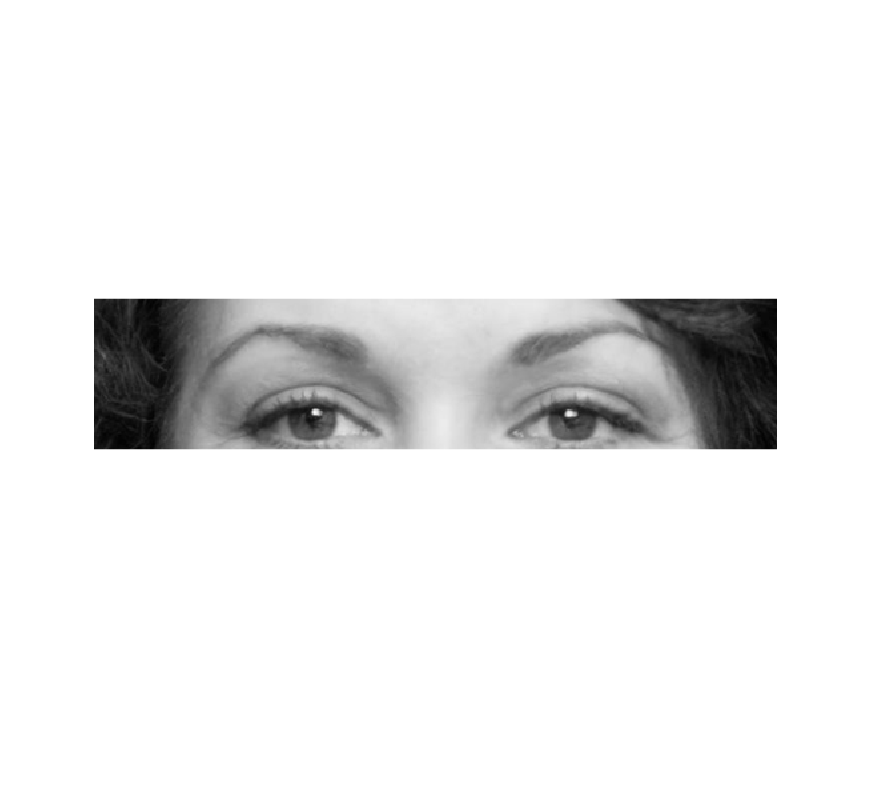

[soloOjos, masOjos, caraMarcada, inicioHorizontal, inicioVertical, factorInverso, inicioVerticalMas, finalHorizontal, finalVertical] = caras(imagen, modelo);

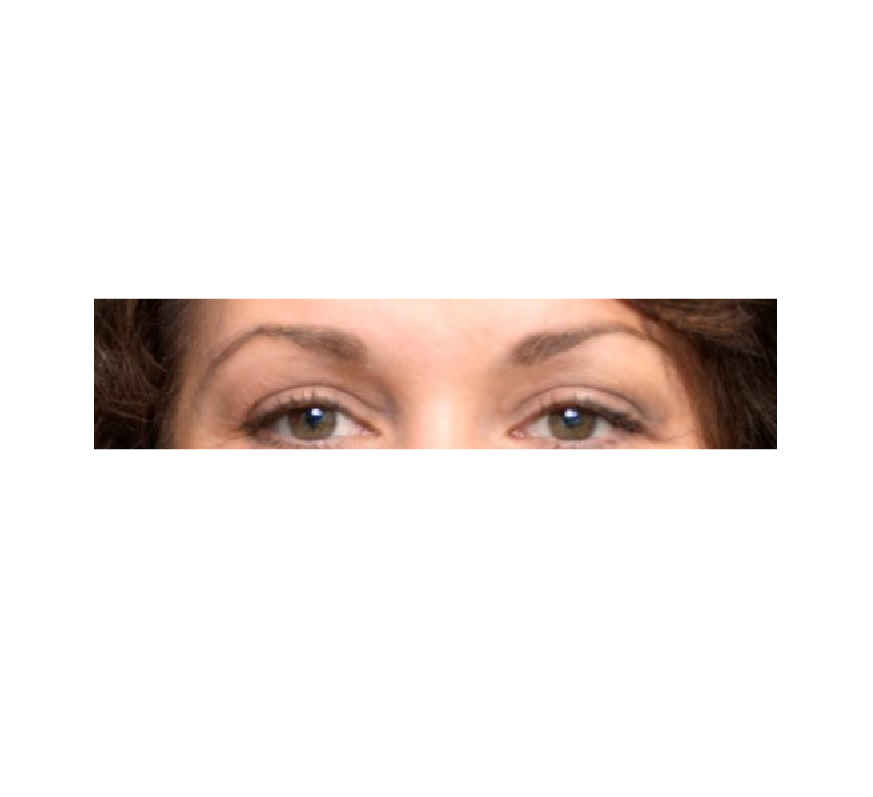

imshow(soloOjos);

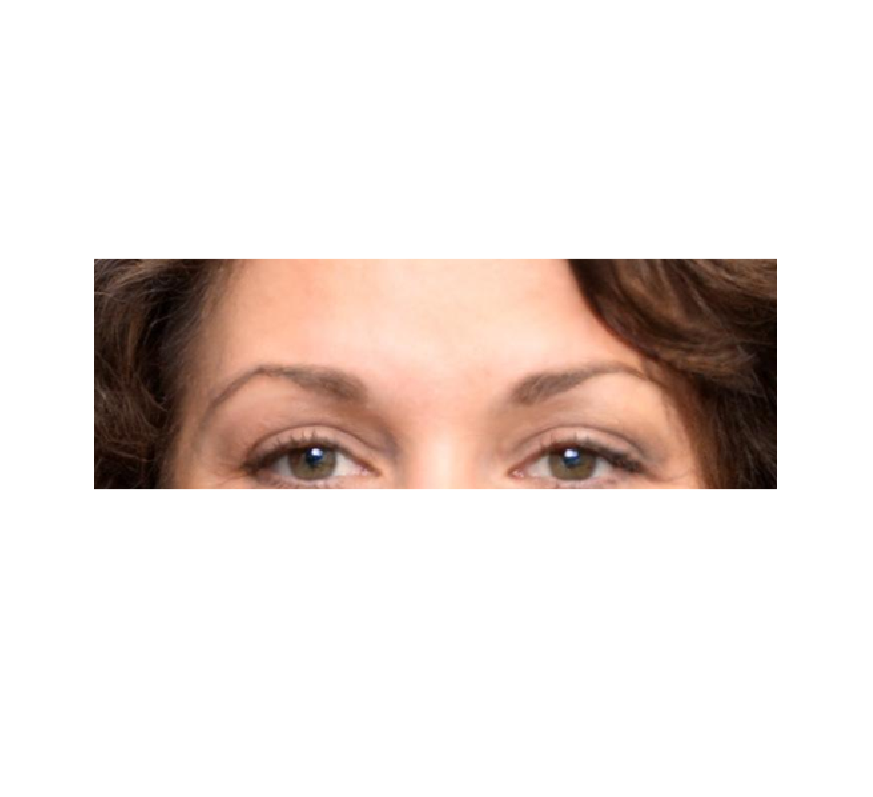

imshow(masOjos);

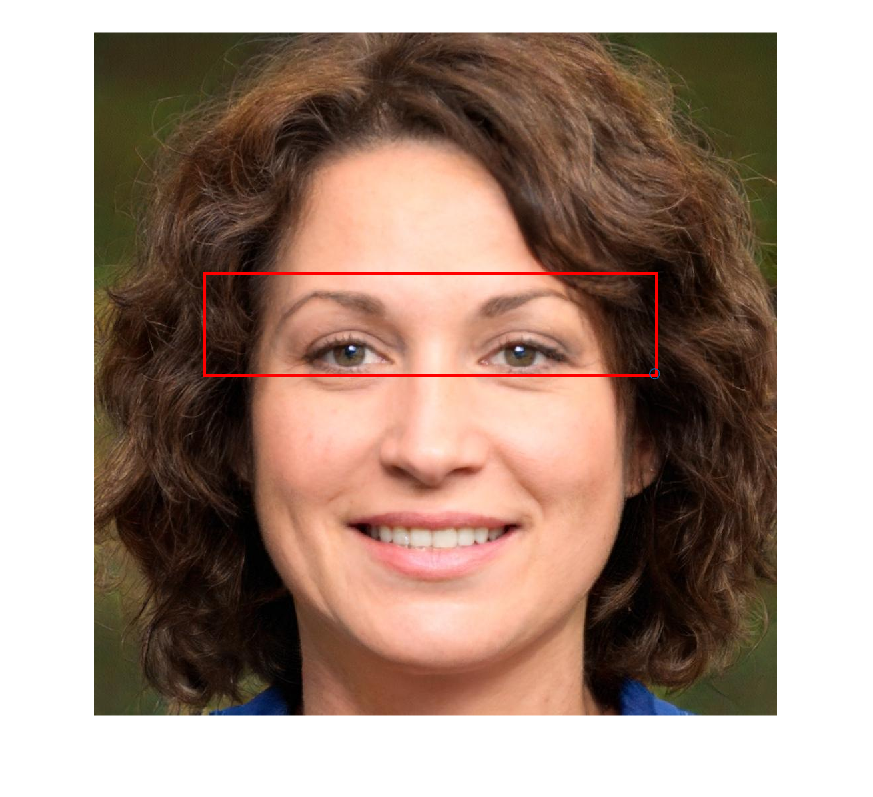

imshow(caraMarcada);
hold on;
plot(finalHorizontal + inicioHorizontal, finalVertical + inicioVertical, 'o');
hold off;

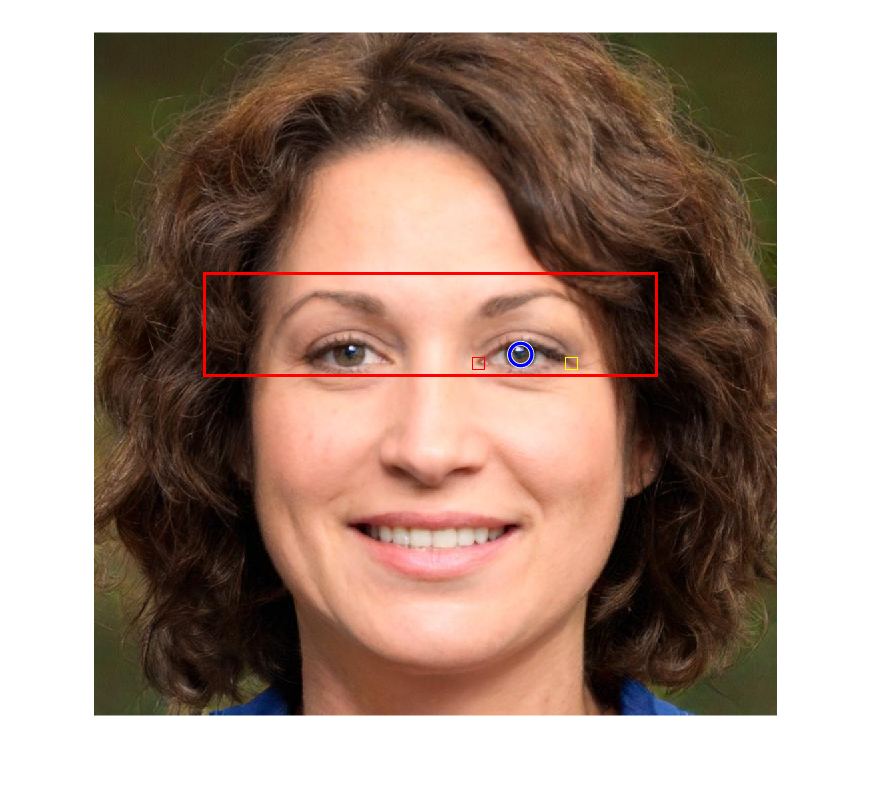

[imin, imax, center, radii, d1, d2, medio] = lagrimal(soloOjos);
inicioHorizontal2 = round(width(soloOjos)/2) * factorInverso;
inicioVertical2 = 0;

imshow(caraMarcada);
center(1) = (center(1) * factorInverso) + inicioHorizontal + inicioHorizontal2;
center(2) = (center(2) * factorInverso) + inicioVertical + inicioVertical2;
hold on;
viscircles(center, radii,'Color','b');
plot(inicioHorizontal + inicioHorizontal2 + (imin * factorInverso), (medio * factorInverso) + inicioVertical + inicioVertical2 , 's','MarkerSize', 10 ,'Color','r');
plot(inicioHorizontal + inicioHorizontal2 + (imax * factorInverso), (medio * factorInverso) + inicioVertical + inicioVertical2, 's','MarkerSize', 10 ,'Color','yellow');
hold off;